[mics, fs] = audioread("double_mics.wav");
error_mic = mics(:, 1);
source_mic = mics(:, 2);

load('double_mic_irs.mat')
error_ir = measurementData(1, 2).ImpulseResponse.Amplitude;
source_ir = measurementData(2, 2).ImpulseResponse.Amplitude;

size(error_ir)

ans =            1      192000


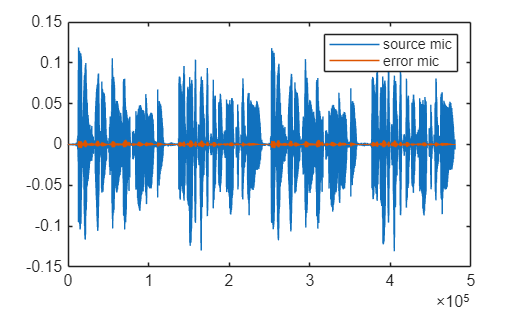

figure
plot(source_mic)
hold on
plot(error_mic)
legend("source mic", "error mic")

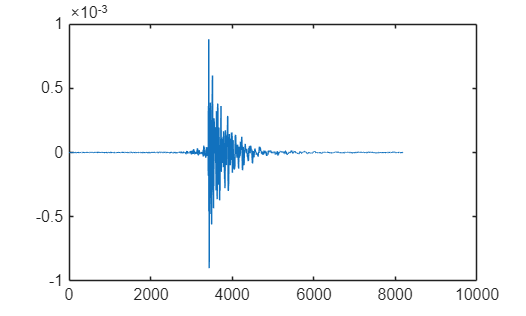

figure
plot(source_ir(1:8192))

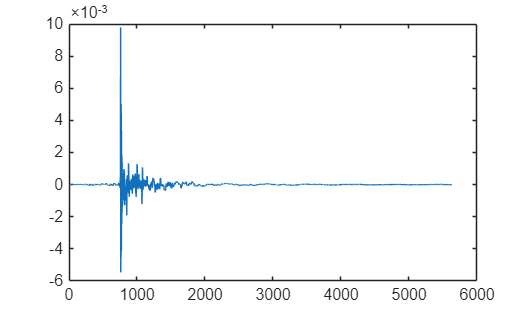

figure
plot(error_ir(2560:8192))

% hold on
% plot(source_ir)
% legend("error ir", "source ir")